## Loading Labels and Redefining Markers for Stimulus Sequence

anta_labels = load('Information/pharma/dprst_anta_druglabels_anonym.mat');

agon_labels = load('Information/pharma/dprst_agon_druglabels_anonym.mat');
tones = load('Information/paradigm/stimulus_sequence.mat');
tones = struct2cell(tones);
tones = [tones{:}];
trial_type = getTrialtype(tones);

standard_idx = find(trial_type == 'standard');
deviant_idx = find(trial_type == 'deviant');

## Extracting EEG Data, Averaging over Standard/Deviants Trials and Associating  Labels

data = struct; % initialize an empty struct to store the data for matlab analysis
python = struct; % initialize an empy struct to store the data for python analysis
list_to_skip = [6, 11, 25, 30, 31, 50, 55, 60, 62, 71];
for i = 1:81
    if ismember(i, list_to_skip)
        continue
    else
        folder_name = sprintf('DPRST_%04d', i+100); % create the folder name string
        file_name = sprintf('%s_MMN_preproc.mat', folder_name); % create the EEG data file name string
        file_path = fullfile('anta', folder_name, file_name); % create the full file path
        eeg_data = spm_eeg_load(file_path); % load the EEG data file
        eeg_chan_idx = eeg_data.indchantype('EEG');
        eeg_data = eeg_data(eeg_chan_idx, :, :);
        standards = eeg_data(:,:,standard_idx);
        deviants = eeg_data(:,:,deviant_idx);
        standards_avg = mean(standards, 3);
        deviants_avg = mean(deviants, 3);
        eeg_averaged = reshape(horzcat(standards_avg, deviants_avg),1,[]);
        subject_id = folder_name(end-3:end); % extract the subject ID from the folder name
        if ismember(subject_id, anta_labels.subjACh.subjIDs)
            drug_label = 'Biperdine' ; % set the drug label to 'Biperdine = 1' if the subject received Biperdine
        elseif ismember(subject_id, anta_labels.subjDA.subjIDs)
            drug_label = 'Amisulpride'; % set the drug label to 'Amisulpride = 2' if the subject received Amisulpride
        elseif ismember(subject_id, anta_labels.subjPla.subjIDs)
            drug_label = 'Placebo'; % set the drug label to 'Placebo = 0' if the subject received Placebo
        else
            drug_label = 'Unknown'; % set the drug label to 'Unknown' if the subject ID is not found in any of the drug label structs
        end
        % add the EEG data, subject ID, and drug label to the data struct
        data(i).subject_id = subject_id;
        data(i).drug_label = drug_label;
        data(i).eeg_data = eeg_averaged;
        python(i).subject_id = subject_id;
        python(i).drug_label = drug_label;
        python(i).standards = standards_avg;
        python(i).deviants = deviants_avg;
    end
end

list_to_skip2 = [144, 158];
for i = 82:161
    if ismember(i, list_to_skip2)
        continue
    else
        folder_name = sprintf('DPRST_%04d', i+119); % create the folder name string
        file_name = sprintf('%s_MMN_preproc.mat', folder_name); % create the EEG data file name string
        file_path = fullfile('agon', folder_name, file_name); % create the full file path
        eeg_data = spm_eeg_load(file_path); % load the EEG data file
        eeg_chan_idx = eeg_data.indchantype('EEG');
        eeg_data = eeg_data(eeg_chan_idx, :, :);
        standards = eeg_data(:,:,standard_idx);
        deviants = eeg_data(:,:,deviant_idx);
        standards_avg = mean(standards, 3);
        deviants_avg = mean(deviants, 3);
        eeg_averaged = reshape(horzcat(standards_avg, deviants_avg),1,[]);
        subject_id = folder_name(end-3:end); % extract the subject ID from the folder name
        if ismember(subject_id, agon_labels.subjACh.subjIDs)
            drug_label = 'Galantamine' ; % set the drug label to 'Biperdine = 1' if the subject received Biperdine
        elseif ismember(subject_id, agon_labels.subjDA.subjIDs)
            drug_label = 'Levodopa'; % set the drug label to 'Amisulpride = 2' if the subject received Amisulpride
        elseif ismember(subject_id, agon_labels.subjPla.subjIDs)
            drug_label = 'Placebo'; % set the drug label to 'Placebo = 0' if the subject received Placebo
        else
            drug_label = 'Unknown'; % set the drug label to 'Unknown' if the subject ID is not found in any of the drug label structs
        end
        % add the EEG data, subject ID, and drug label to the data struct
        data(i).subject_id = subject_id;
        data(i).drug_label = drug_label;
        data(i).eeg_data = eeg_averaged;
        python(i).subject_id = subject_id;
        python(i).drug_label = drug_label;
        python(i).standards = standards_avg;
        python(i).deviants = deviants_avg;
    end
end

## Dataframe for Matlab

data_table = struct2table(data);
remove_blanks = horzcat(list_to_skip, list_to_skip2);
data_table(remove_blanks, :) = [];
writetable(data_table, '5Drugs.csv');

data_drugs = readtable('5Drugs.csv', 'ReadVariableNames', true);

## Dataframe for Python

%python_table = struct2table(python);
%remove_blanks = horzcat(list_to_skip, list_to_skip2);
%python_table(remove_blanks, :) = [];
%writetable(python_table, '5Drugs_Python.csv');

## Cross-Validated Classification (Without Embedding)

#### Original Labels Classification

[accuracies_rf, accuracies_adb, accuracies_knn, accuracies_svm] = accuracies_RAW(data_drugs, 3);

#### Permuted Labels Classification 

[accuracies_rf_perm, accuracies_adb_perm, accuracies_knn_perm, accuracies_svm_perm] = accuracies_RAW_perm(data_drugs, 30, 0);

#### Plotting

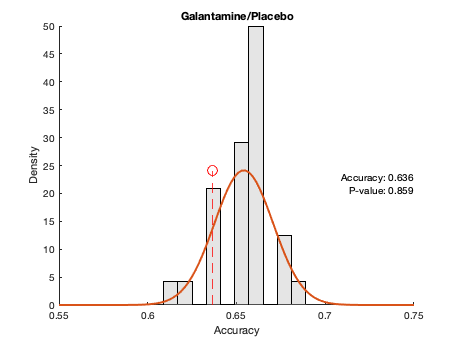

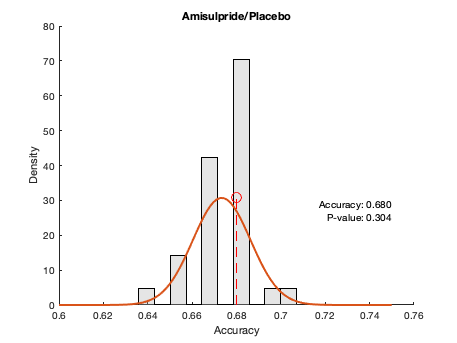

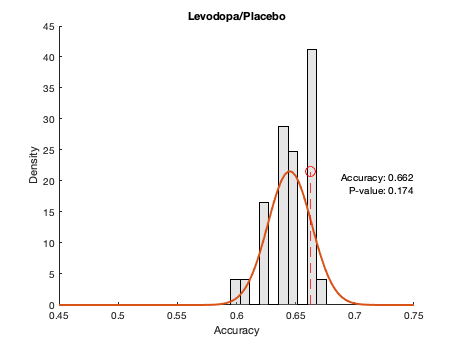

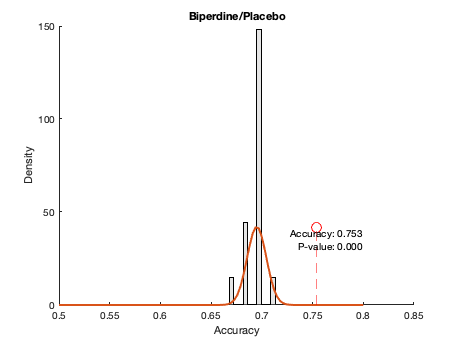

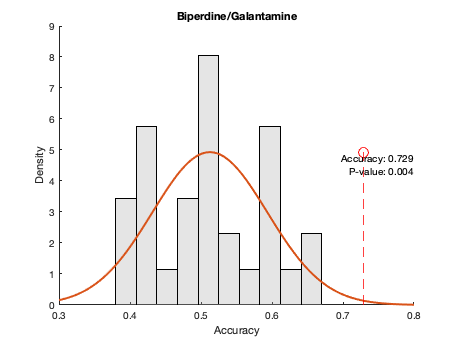

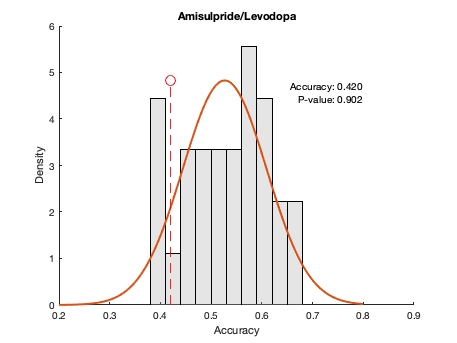

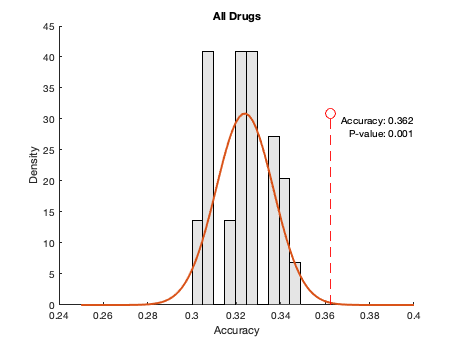

plotting_RAW("rf", accuracies_rf_perm, accuracies_rf);

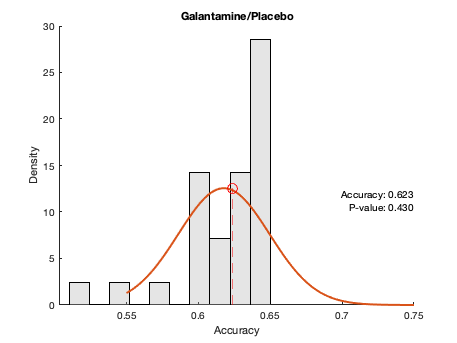

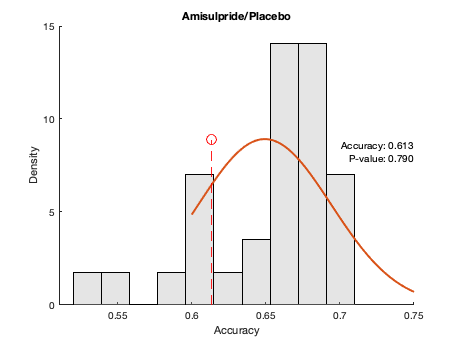

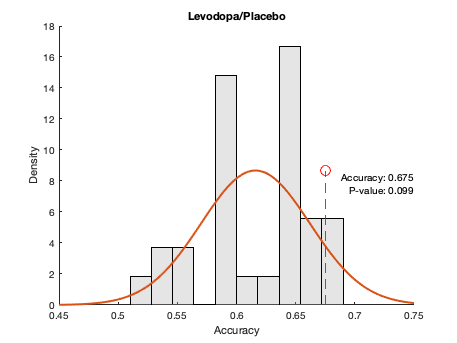

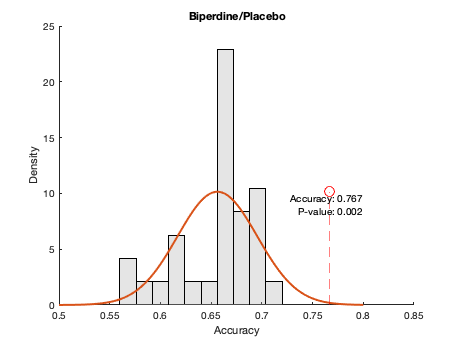

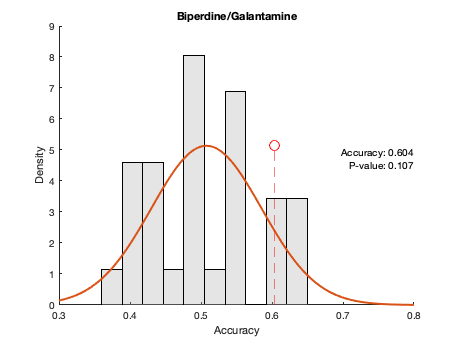

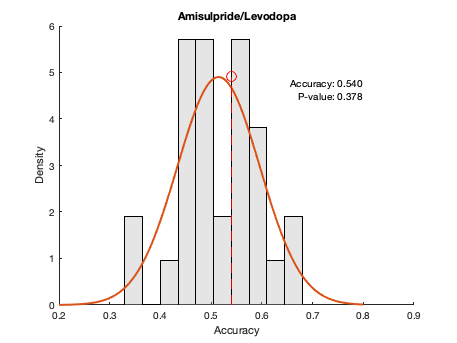

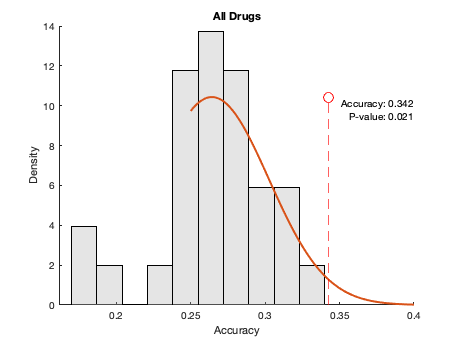

plotting_RAW("knn", accuracies_knn_perm, accuracies_knn);

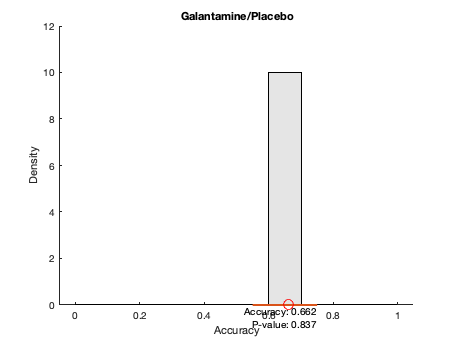

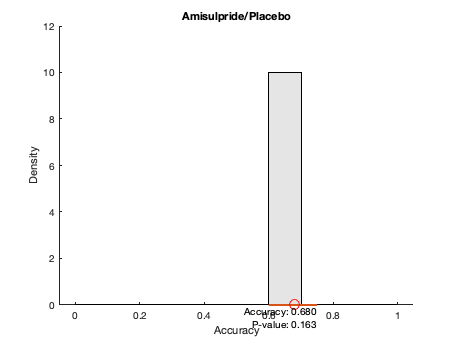

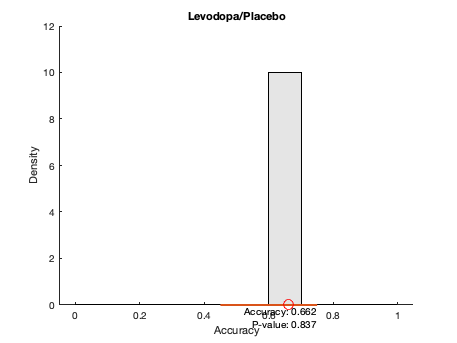

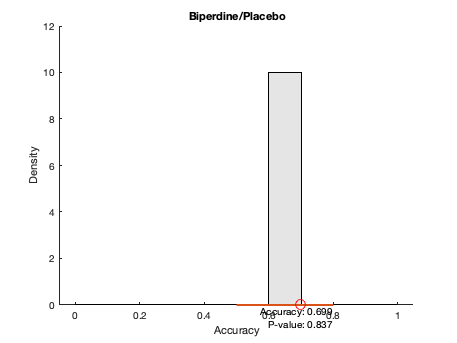

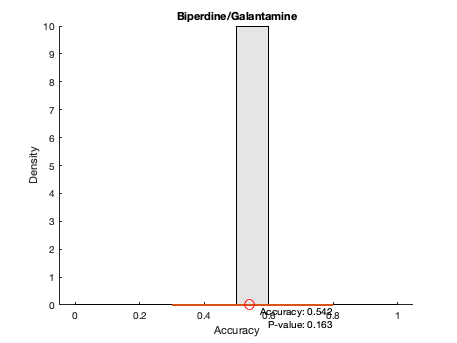

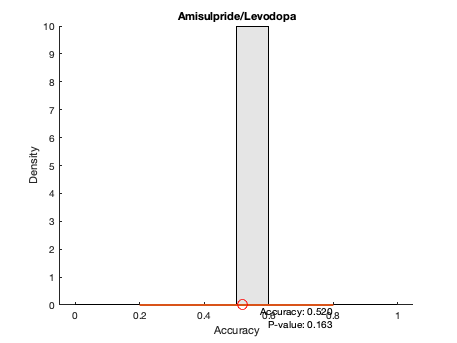

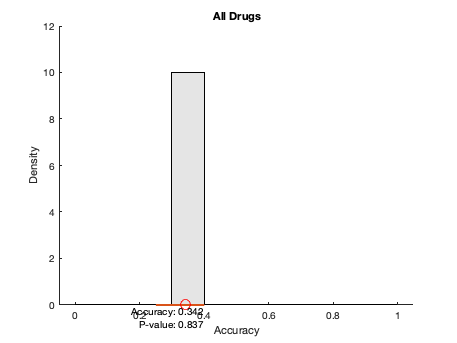

plotting_RAW("adb", accuracies_adb_perm, accuracies_adb);

plotting_RAW("svm", accuracies_svm_perm, accuracies_svm);

### Optimization Models without Embedding

#### Tree Bagger Bayesian Optimization using Quantile Error

%rng ('default');
%X = table2array(data_drugs(:,3:end));
%y = table2array(data_drugs(:,2));
%maxMinLS = 20;
%minLS = optimizableVariable('minLS',[1,maxMinLS],'Type','integer');
%numPTS = optimizableVariable('numPTS',[1,size(X,2)-1],'Type','integer');
%hyperparametersRF = [minLS; numPTS];

%results = bayesopt(@(params)oobErrRF(params,X,y),hyperparametersRF, 'AcquisitionFunctionName','expected-improvement-plus','Verbose',1);

%bestOOBErr = results.MinObjective
%bestHyperparameters = results.XAtMinObjective

%tb_tuned = TreeBagger(300,X,y,'Method','classification', 'MinLeafSize',bestHyperparameters.minLS, 'NumPredictorstoSample',bestHyperparameters.numPTS);


#### Tree Ensemble Optimization

%rng('default');
%ensemble_tuned = fitcensemble(X,y, 'Method','AdaBoostM2', 'OptimizeHyperparameters',{'NumLearningCycles','LearnRate','MaxNumSplits'})

#### SVM Optimization

%rng('default');
%svm_tuned = fitcecoc(X,y,'OptimizeHyperparameters','auto', 'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', 'expected-improvement-plus'))

#### KNN Optimization

%rng('default');
%knn_tuned = fitcknn(X,y,'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions', struct('AcquisitionFunctionName','expected-improvement-plus'))

## Dimensionality Reduction via Laplacian Eigenmaps Embedding + Cross-Validated Classification

#### Original Label Classification

[accuracies_rf_laplacian, accuracies_adb_laplacian, accuracies_knn_laplacian, accuracies_svm_laplacian] = accuracies_LAPLACE(data_drugs, 17);

#### Permuted Labels Classification 

[accuracies_rf_laplacian_perm, accuracies_adb_laplacian_perm, accuracies_knn_laplacian_perm, accuracies_svm_laplacian_perm] = accuracies_LAPLACE_perm(data_drugs, 30, 0);

#### Plotting

plotting_LAPLACE("rf", accuracies_rf_laplacian_perm, accuracies_rf_laplacian);

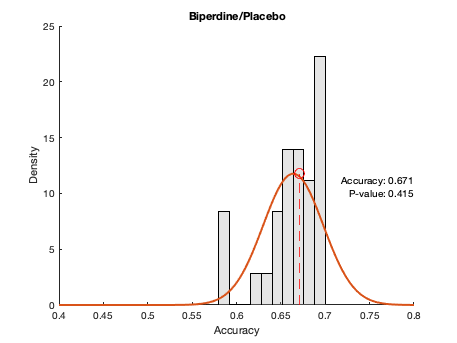

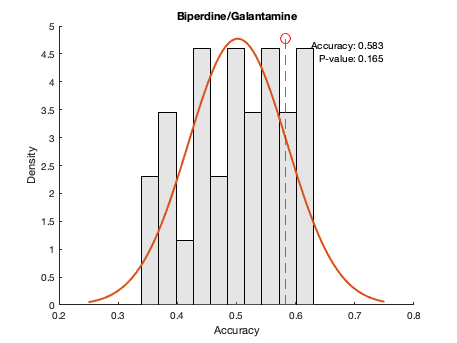

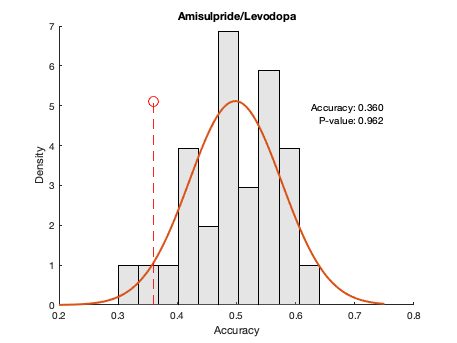

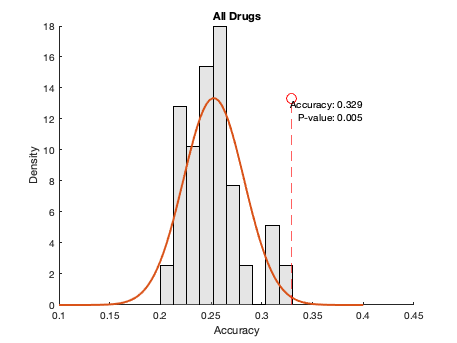

plotting_LAPLACE("knn", accuracies_knn_laplacian_perm, accuracies_knn_laplacian);

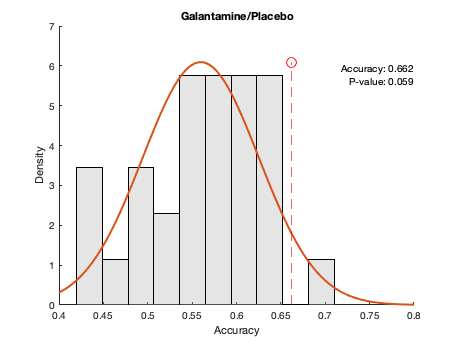

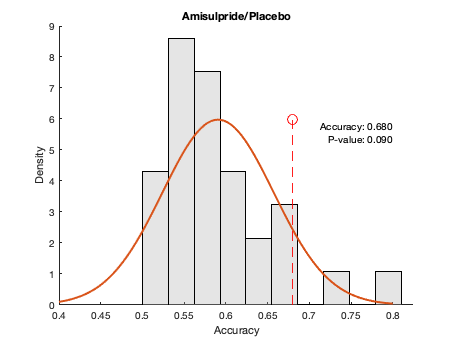

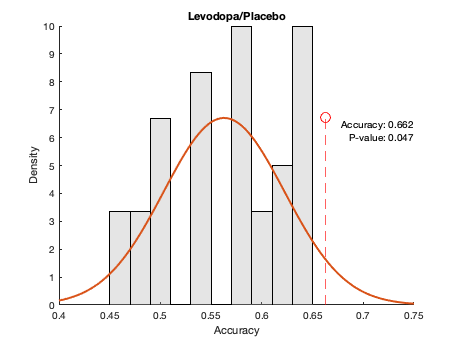

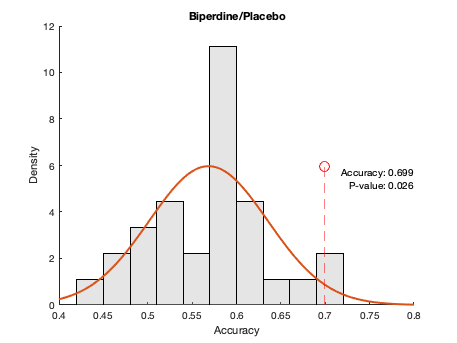

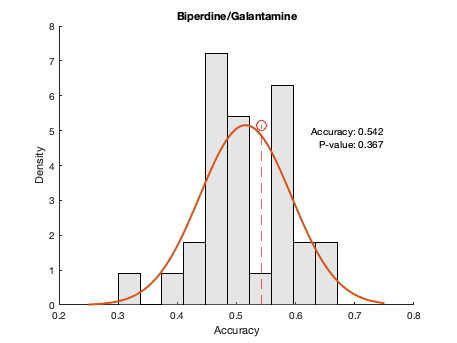

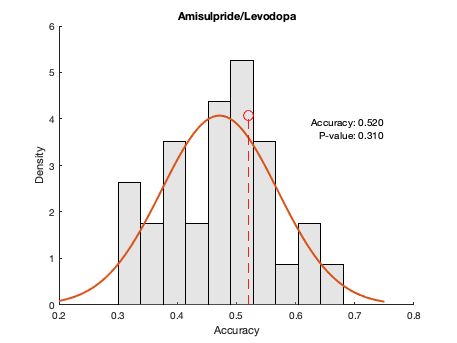

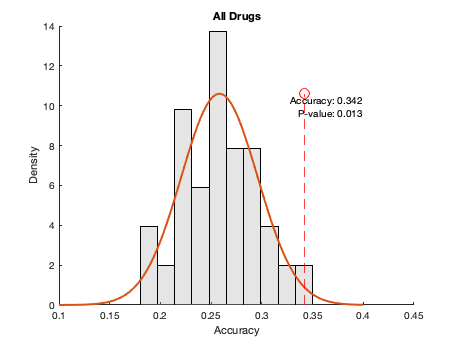

plotting_LAPLACE("adb", accuracies_adb_laplacian_perm, accuracies_adb_laplacian);

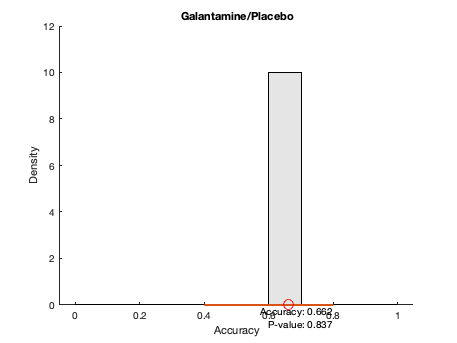

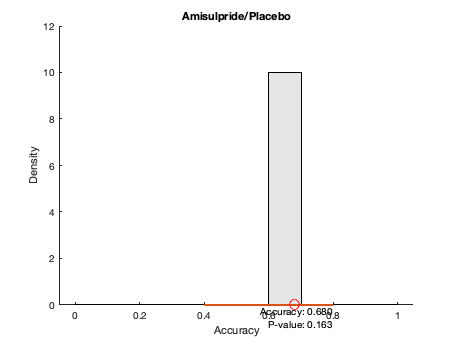

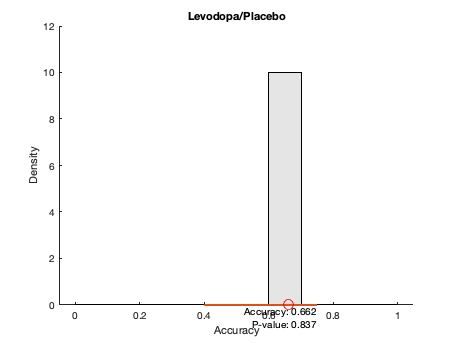

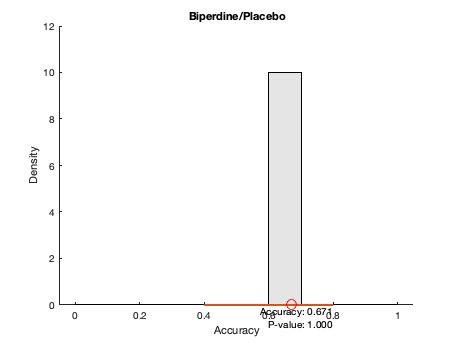

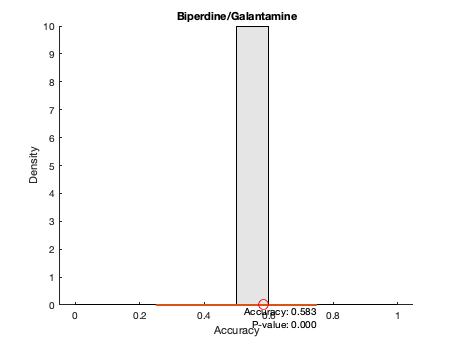

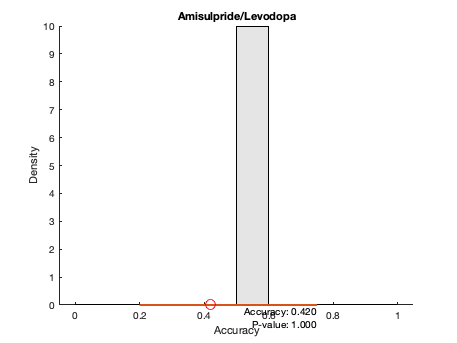

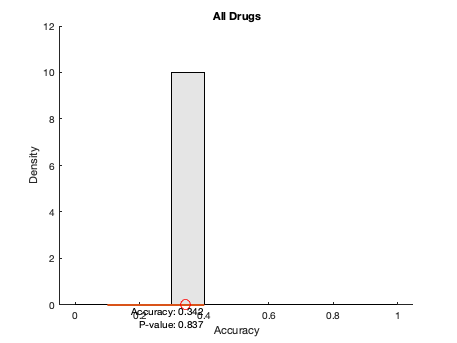

plotting_LAPLACE("svm", accuracies_svm_laplacian_perm, accuracies_svm_laplacian);

### Optimization Models with Laplacian Eigenmaps Embedding

#### Tree Bagger Bayesian Optimization using Quantile Error

%rng ('default');
% Set options for embedding
%opts = {'Distance', 'Euclidean', 'Sigma', 1, 'NumNeighbors', 10, 'NumDimensions', 2, 'Verbose', 1};
%X = table2array(data_drugs(:,3:end));
%X = laplacianEigenmaps(X, opts{:});
%y = table2array(data_drugs(:,2));
%maxMinLS = 20;
%minLS = optimizableVariable('minLS',[1,maxMinLS],'Type','integer');
%numPTS = optimizableVariable('numPTS',[1,20],'Type','integer');
%hyperparametersRF = [minLS; numPTS];

%results = bayesopt(@(params)oobErrRF(params,X,y),hyperparametersRF, 'AcquisitionFunctionName','expected-improvement-plus','Verbose',1);

%bestOOBErr = results.MinObjective
%bestHyperparameters = results.XAtMinObjective

%tb_tuned_laplacian = TreeBagger(300,X,y,'Method','classification', 'MinLeafSize',bestHyperparameters.minLS, 'NumPredictorstoSample',bestHyperparameters.numPTS);


#### Tree Ensemble Optimization

%rng('default');
%ensemble_tuned_laplacian = fitcensemble(X,y, 'Method','AdaBoostM2', 'OptimizeHyperparameters',{'NumLearningCycles','LearnRate','MaxNumSplits'})

#### SVM Optimization

%rng('default');
%svm_tuned_laplacian = fitcecoc(X,y,'OptimizeHyperparameters','auto', 'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', 'expected-improvement-plus'))

#### KNN Optimization

%rng('default');
%knn_tuned_laplacian = fitcknn(X,y,'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions', struct('AcquisitionFunctionName','expected-improvement-plus'))

## Generative Embedding via DCM + Cross-Validated Classification

#### Original Label Classification

dcm_table = load("dcmOutputTable.mat");
[accuracies_rf_DCM, accuracies_adb_DCM, accuracies_knn_DCM, accuracies_svm_DCM] = accuracies_DCM(dcm_table, 3);

#### Permuted Labels Classification

[accuracies_rf_DCM_perm, accuracies_adb_DCM_perm, accuracies_knn_DCM_perm, accuracies_svm_DCM_perm] = accuracies_DCM_perm(dcm_table, 30, 0);

#### Plotting

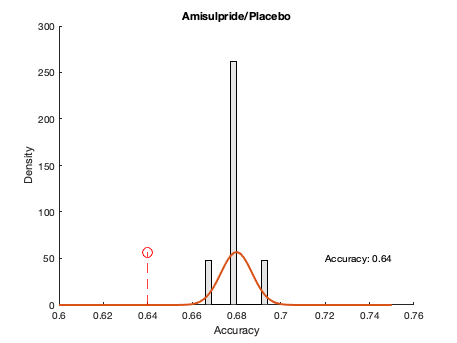

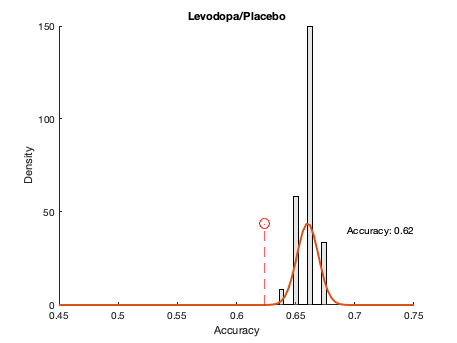

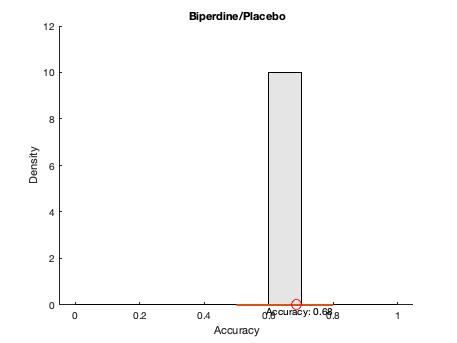

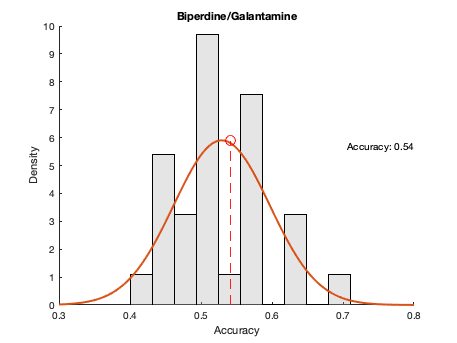

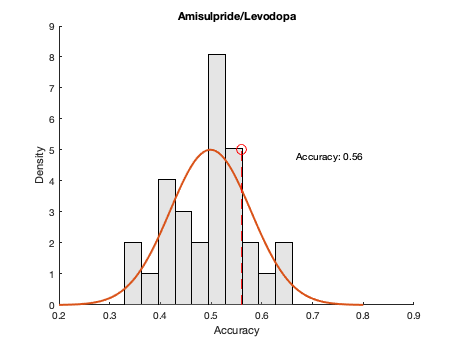

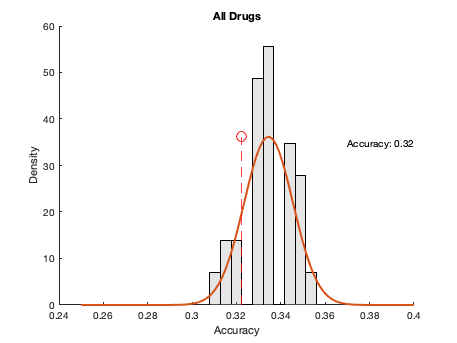

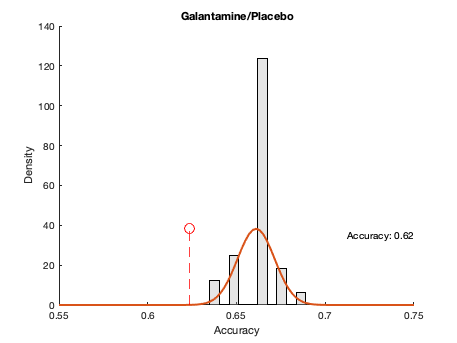

plotting_DCM("rf", accuracies_rf_DCM_perm, accuracies_rf_DCM);

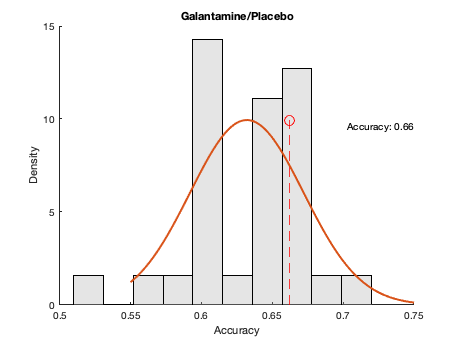

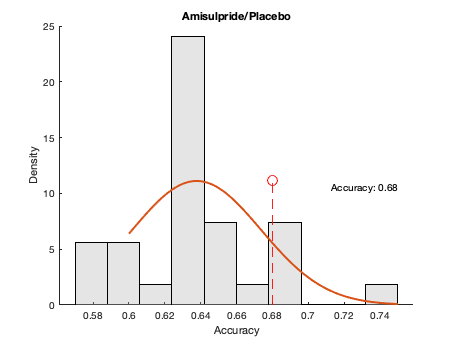

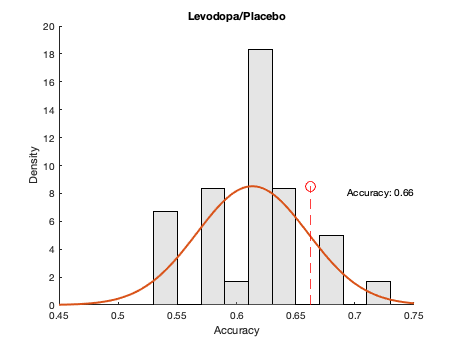

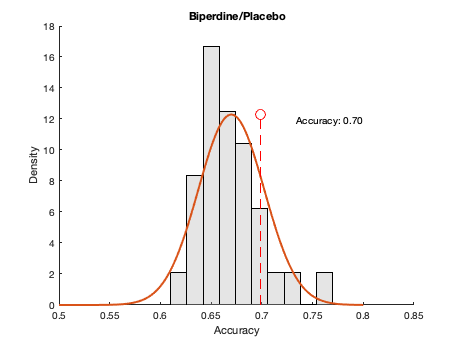

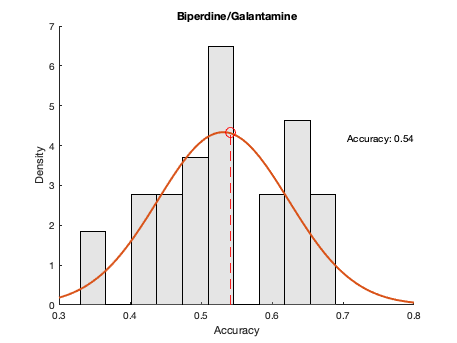

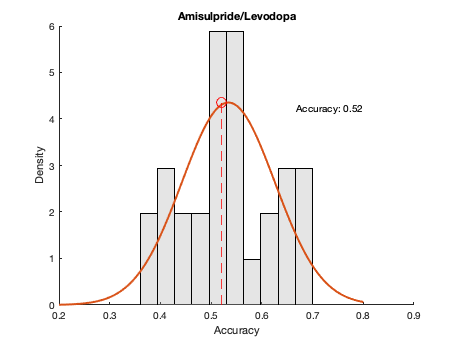

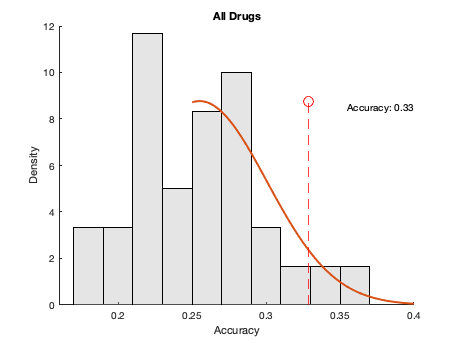

plotting_DCM("knn", accuracies_knn_DCM_perm, accuracies_knn_DCM);

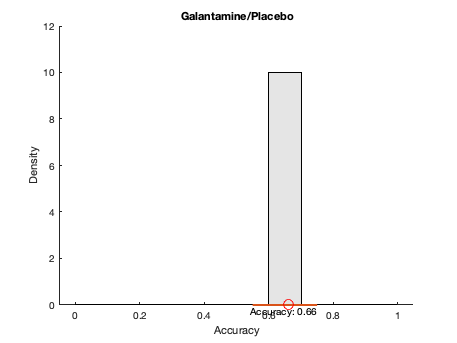

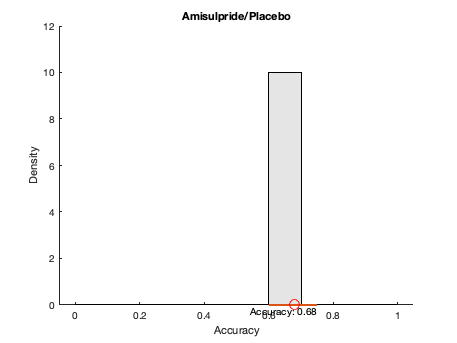

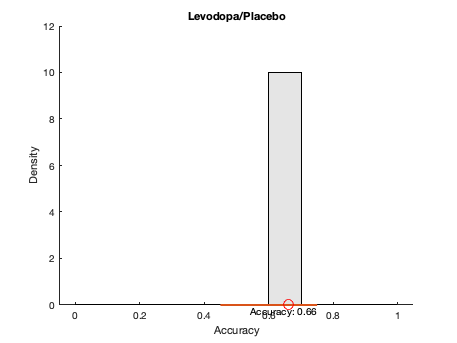

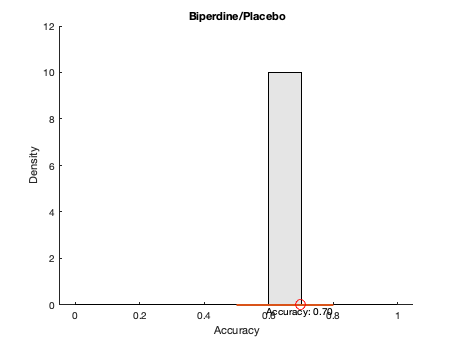

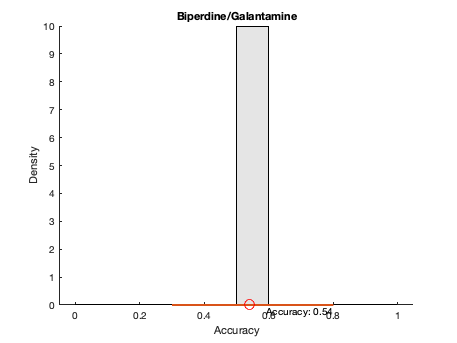

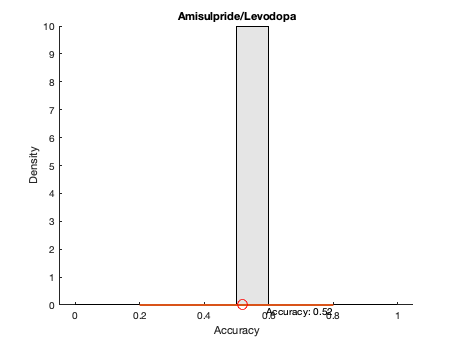

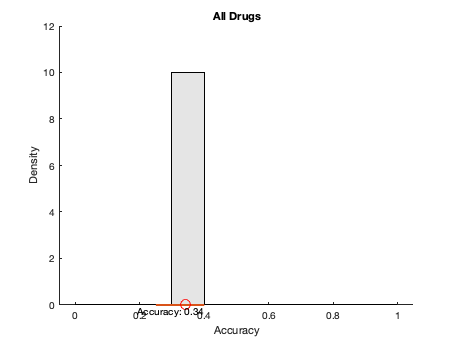

plotting_DCM("adb", accuracies_adb_DCM_perm, accuracies_adb_DCM);

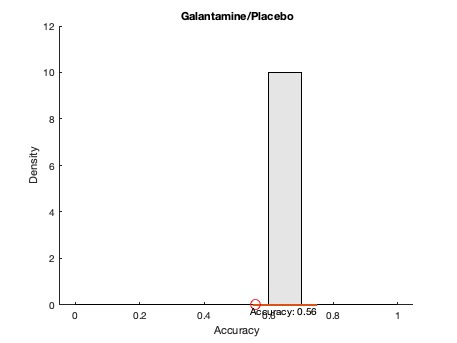

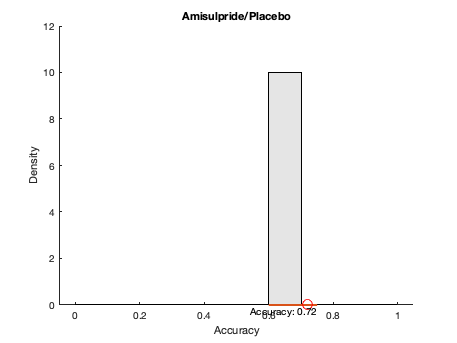

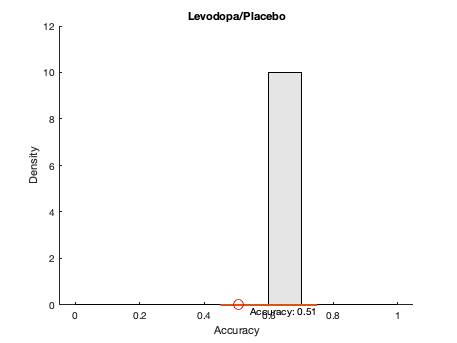

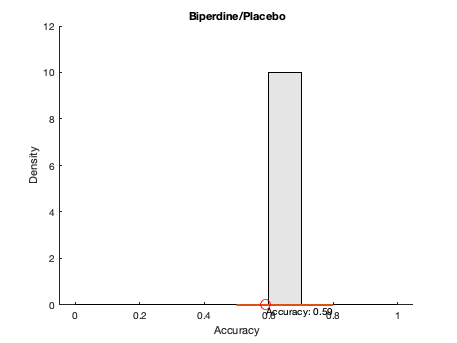

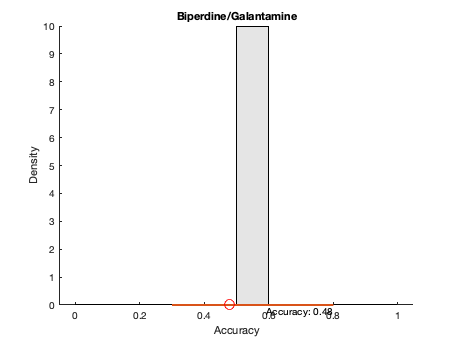

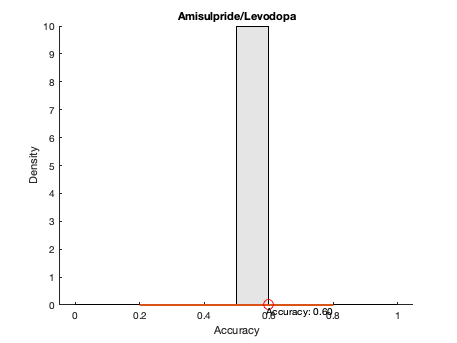

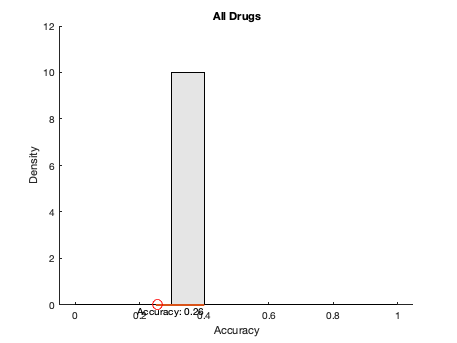

plotting_DCM("svm", accuracies_svm_DCM_perm, accuracies_svm_DCM);

### Optimization Models with DCM Embedding

#### Tree Bagger Bayesian Optimization using Quantile Error

%rng ('default');
%X = X_DCM;
%y = y_DCM;

%maxMinLS = 20;
%minLS = optimizableVariable('minLS',[1,maxMinLS],'Type','integer');
%numPTS = optimizableVariable('numPTS',[1,20],'Type','integer');
%hyperparametersRF = [minLS; numPTS];

%results = bayesopt(@(params)oobErrRF(params,X,y),hyperparametersRF, 'AcquisitionFunctionName','expected-improvement-plus','Verbose',1);

%bestOOBErr = results.MinObjective
%bestHyperparameters = results.XAtMinObjective

%tb_tuned_DCM = TreeBagger(300,X,y,'Method','classification', 'MinLeafSize',bestHyperparameters.minLS, 'NumPredictorstoSample',bestHyperparameters.numPTS);


#### Tree Ensemble Optimization

%rng('default');
%ensemble_tuned_DCM = fitcensemble(X,y, 'Method','AdaBoostM2', 'OptimizeHyperparameters',{'NumLearningCycles','LearnRate','MaxNumSplits'})

#### SVM Optimization

%rng('default');
%svm_tuned_DCM = fitcecoc(X,y,'OptimizeHyperparameters','auto', 'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', 'expected-improvement-plus'))

#### KNN Optimization

%rng('default');
%knn_tuned_DCM = fitcknn(X,y,'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions', struct('AcquisitionFunctionName','expected-improvement-plus'))

function oobErr = oobErrRF(params,X,y)
%oobErrRF Trains random forest and estimates out-of-bag quantile error
%   oobErr trains a random forest of 300 regression trees using the
%   predictor data in X and the parameter specification in params, and then
%   returns the out-of-bag quantile error based on the median. X is a table
%   and params is an array of OptimizableVariable objects corresponding to
%   the minimum leaf size and number of predictors to sample at each node.
randomForest = TreeBagger(300,X,y,'Method','classification',...
    'OOBPrediction','on','MinLeafSize',params.minLS,...
    'NumPredictorstoSample',params.numPTS);
oobErr = oobError(randomForest, 'Mode','ensemble');
end